# MLPR Assignment 2

Chris Sipola (s1667278)

2016-11-22

## Question 1: Getting started.

% Load X_test, X_train, X_val, y_test, y_train, y_val.
load('/afs/inf.ed.ac.uk/group/teaching/mlprdata/ctslice/ct_data.mat')

## Part a.

mean = -9.2497e-15 +/- 0.0049535


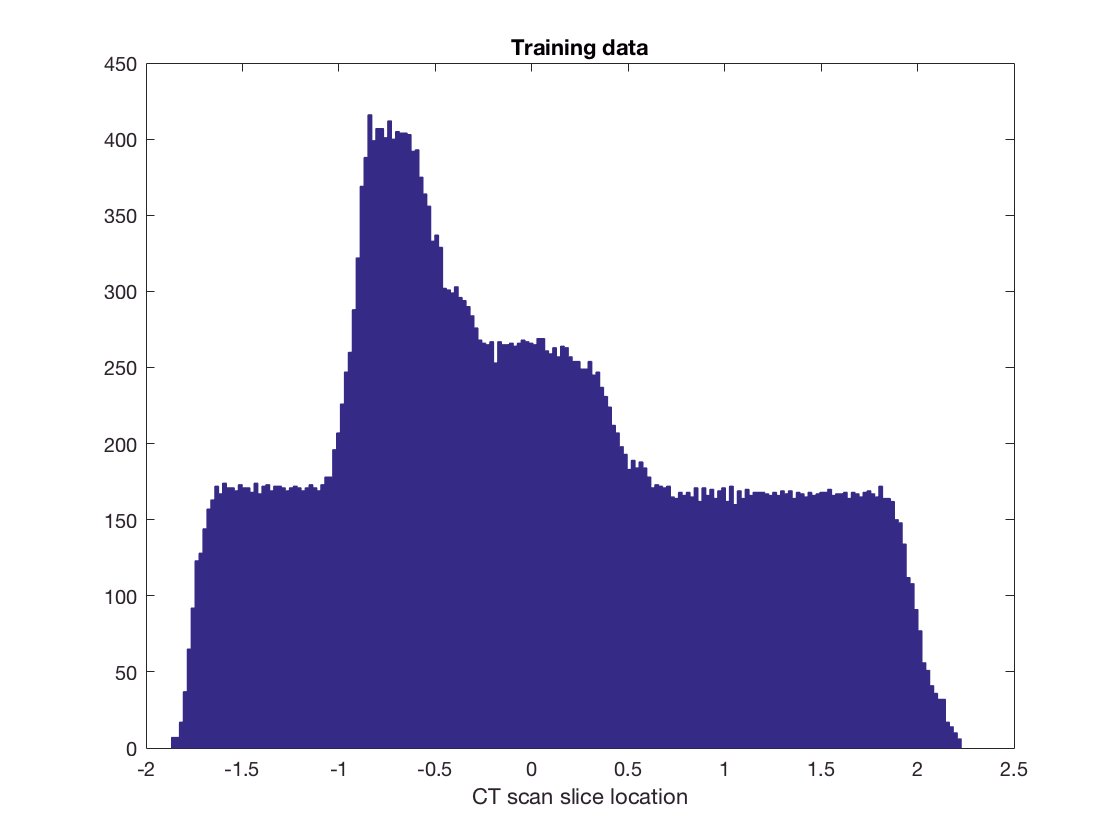

% Verify that the mean of y_train is zero.
explore_dist(y_train, 'Training data');

mean = -0.21601 +/- 0.012904


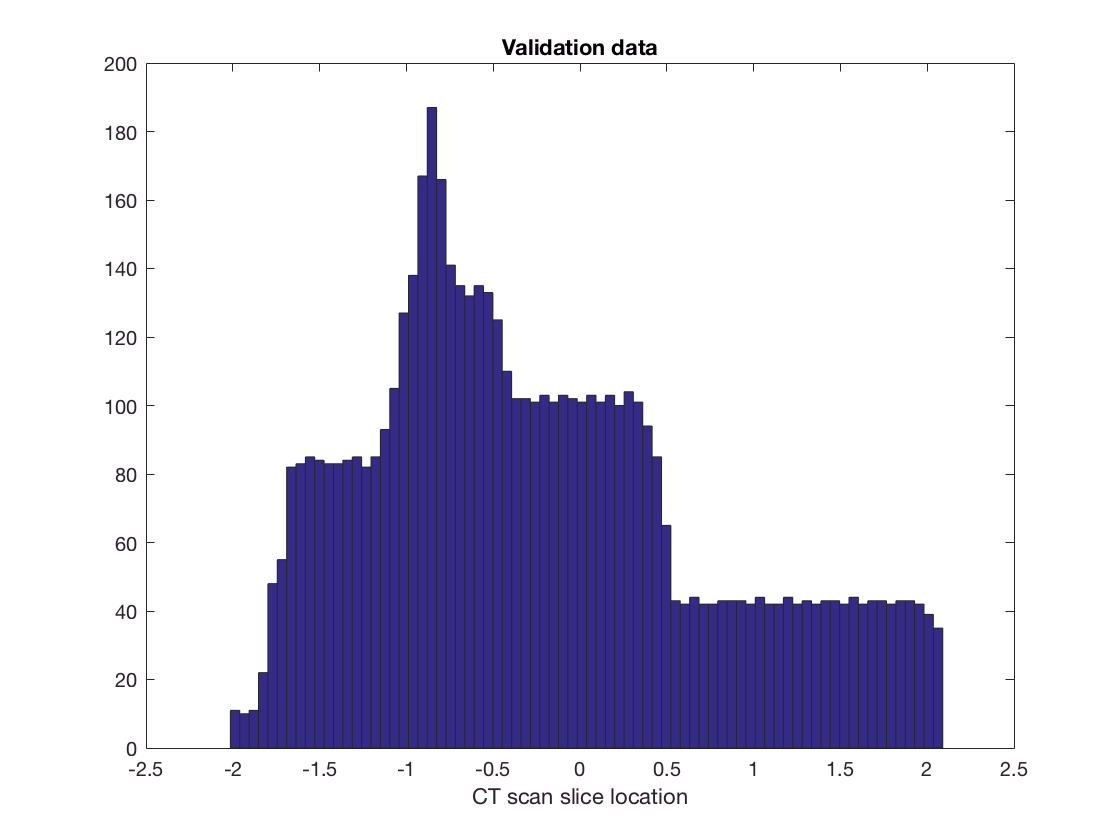


% Verify that the mean of y_val is *not* zero.
explore_dist(y_val, 'Validation data');

mean = -0.44248 +/- 0.011927


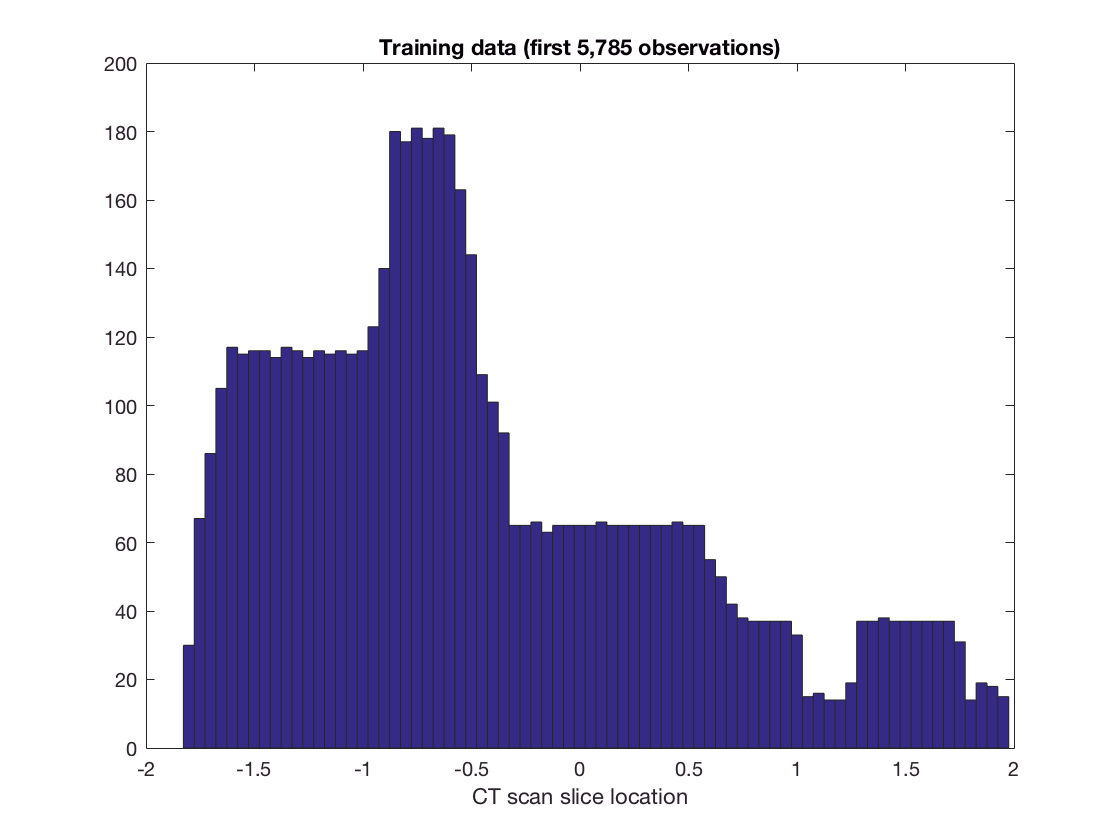


% Compare to mean of beginning of y_train (also not zero). 
explore_dist(y_train(1:5785), 'Training data (first 5,785 observations)');

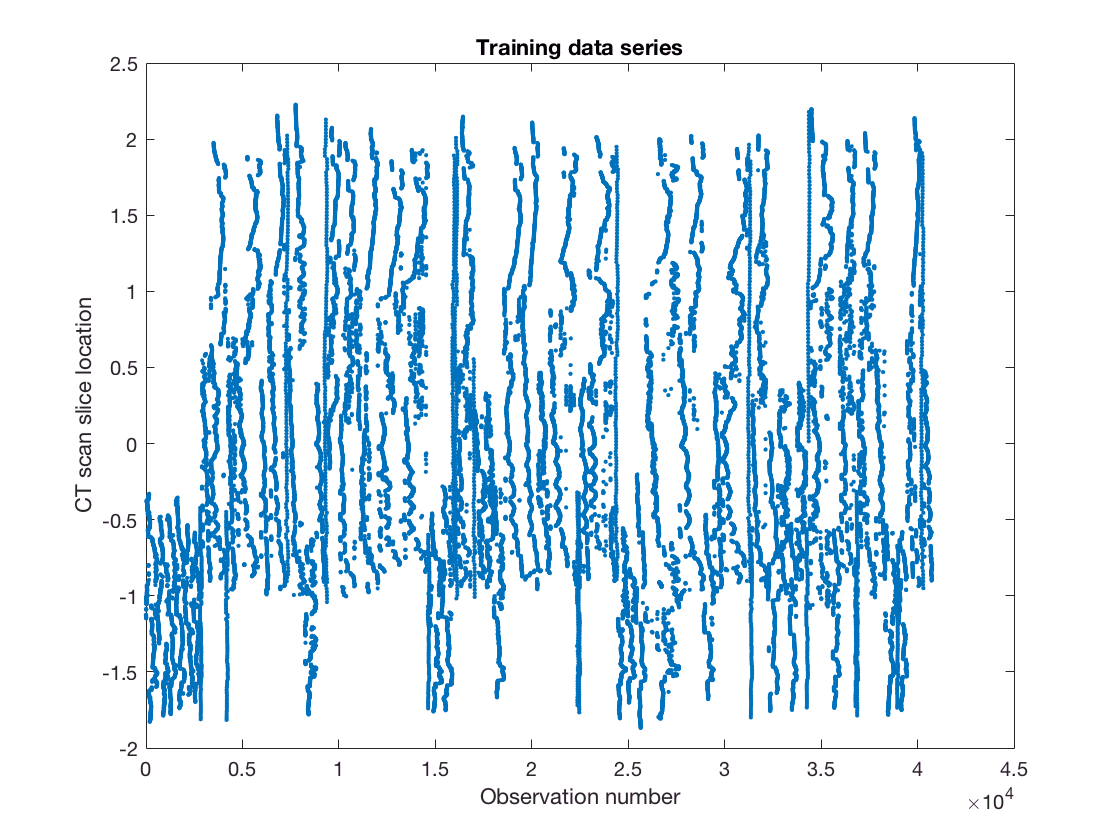


% Explore a bit further with a series plot.
plot(y_train, '.');
title('Training data series');
xlabel('Observation number');
ylabel('CT scan slice location');

We see that the mean changes across the data set. Entries are not independent. This means that the estimate of the mean of a continuous chunk of observations (like in observations 1 to 5,785 in `y_train`) is not a good estimate of the mean in other parts of the data set.

## Part b.

% Identify columns to drop.
cols_to_drop_idx = max(X_train) - min(X_train) == 0;
cols_to_drop = find(cols_to_drop_idx)

cols_to_drop =     60    70   180   190   352



% Drop bad columns.
X_train = X_train(:, ~cols_to_drop_idx);
X_val = X_val(:, ~cols_to_drop_idx);
X_test = X_test(:, ~cols_to_drop_idx);

## Question 2: Linear regressgion baseline.

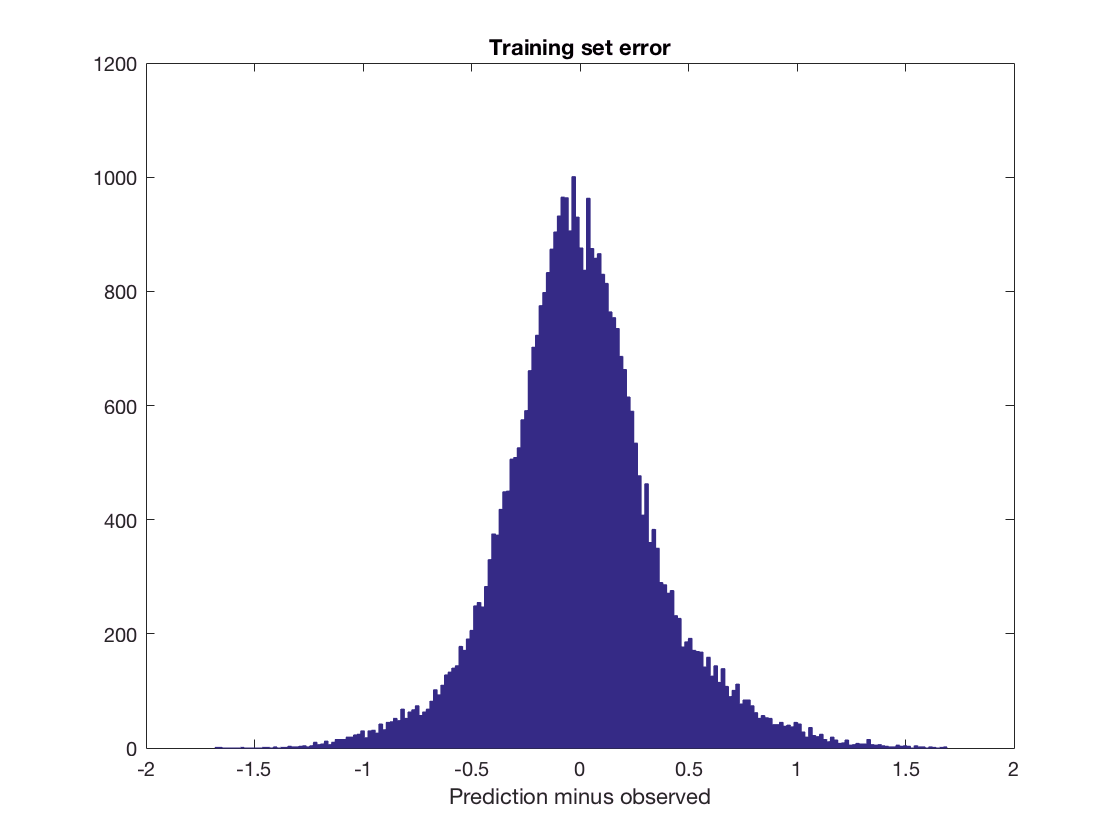

% Set regularization constant.
alpha = 10;

% Fit the weights using the least squares operator.
[ww1, bb1] = fit_linreg(X_train, y_train, alpha);
ff1 = X_train * ww1 + bb1;

% Create histogram of error to make sure it looks reasonable.
hist(ff1 - y_train, sqrt(size(y_train, 1)))
title('Training set error');
xlabel('Prediction minus observed');

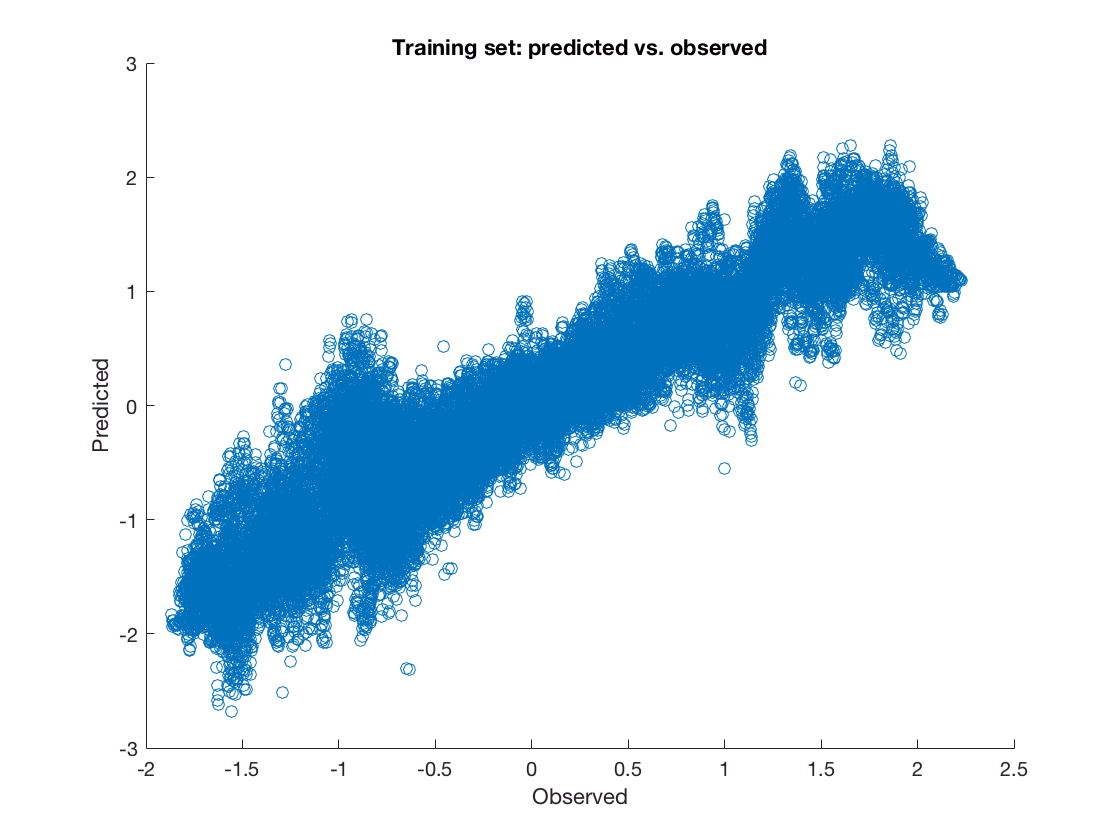


% Create scatter plot of error.
scatter(y_train, ff1)
title('Training set: predicted vs. observed');
xlabel('Observed');
ylabel('Predicted');

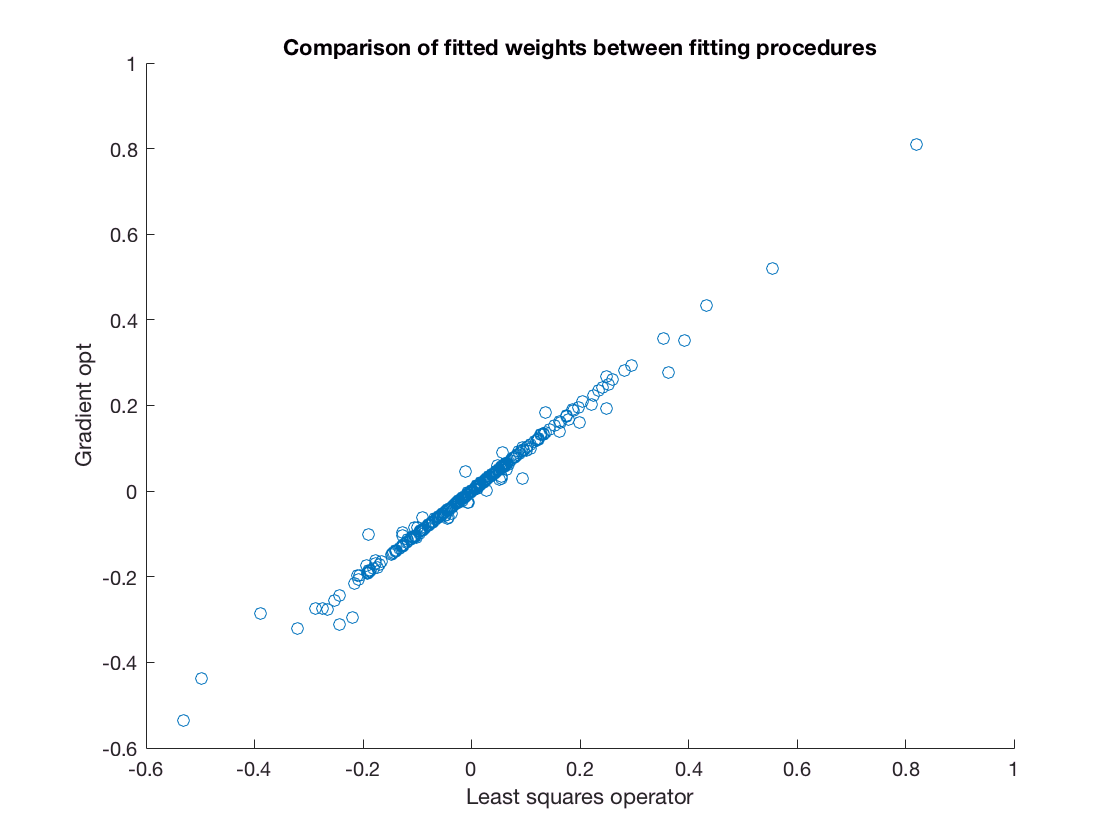


% Fit weights using gradient optimization.
% Use evalc() to suppress console output from fit_linreg_gradopt().
[console_output, ww2, bb2] = evalc('fit_linreg_gradopt(X_train, y_train, alpha);');
ff2 = X_train * ww2 + bb2;

% Compare weights between fitting procedures.
scatter(ww1, ww2);
title('Comparison of fitted weights between fitting procedures');
xlabel('Least squares operator');
ylabel('Gradient opt');


% Calculate RMSE for training set.
disp('Training RMSE, least squares operator: ' + string(rmse(ff1 - y_train)))

Training RMSE, least squares operator: 0.35566


disp('Training RMSE, gradient opt:           ' + string(rmse(ff2 - y_train)))

Training RMSE, gradient opt:           0.35584



% Apply weights to the validation set.
ff1 = X_val * ww1 + bb1;
ff2 = X_val * ww2 + bb2;

% Calculate RMSE for validation set.
disp('Validation RMSE, least squares operator: ' + string(rmse(ff1 - y_val)))

Validation RMSE, least squares operator: 0.42001


disp('Validation RMSE, gradient opt:           ' + string(rmse(ff2 - y_val)))

Validation RMSE, gradient opt:           0.42051


The results between the two fitting procedures are not the same, as you can see from the difference in the weights and the difference in the error values. This is because the first procedure solves for the solution directly, while the second procedure searches for it (and may get very close but not exactly there).

## Question 3: Decreasing and increasing the input dimensionality.

## Part a.

Note: Although the question asks for just K = 10 and K = 100, I will also test values in between to inspect the training and validation error curves.

% Make zero-mean data sets. 
X_train_zero_mean = X_train - mean(X_train, 1);
X_val_zero_mean = X_val - mean(X_val, 1);
V = pca_zm_proj(X_train_zero_mean, 100);

% Test values between 10 and 100 to get shape of training and validation errors.
k_increment = 2;
k_values = 10:k_increment:100;

% Initialize error vectors.
E_train = inf(size(k_values, 2), 1);
E_val = inf(size(k_values, 2), 1);
k_idx = 1;

for kk = k_values
    
    V_kdim = V(:, 1:kk);
    
    % Fit weights on training set.
    X_kdim = X_train_zero_mean * V_kdim;
    [ww, bb] = fit_linreg(X_kdim, y_train, alpha);
    ff = X_kdim * ww + bb;
    E_train(k_idx) = rmse(ff - y_train);
    
    % Apply weights to validation set.
    X_kdim = X_val_zero_mean * V_kdim;
    ff = X_kdim * ww + bb;
    E_val(k_idx) = rmse(ff - y_val);
    
    k_idx = k_idx + 1;
    
end


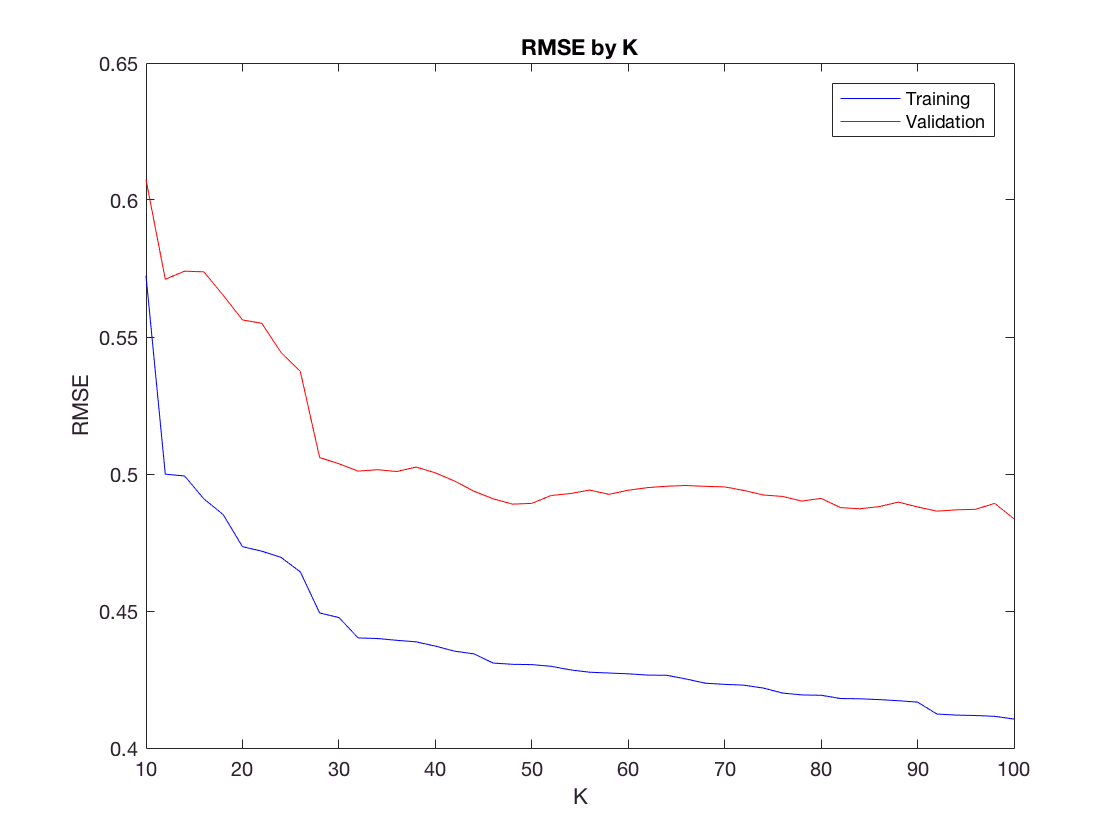


% Create plot for training and validation errors by K.
clf;
plot(k_values, E_train, 'b');
hold on;
plot(k_values, E_val, 'r');
title('RMSE by K');
legend('Training', 'Validation');
xlabel('K');
ylabel('RMSE');
hold off;


[M, K_idx] = min(E_val);
K_best = k_values(K_idx);
K_best

K_best = 100


% Get training error for best K.
E_train(K_idx)

ans = 0.4106


% Get validation error for best K.
E_val(K_idx)

ans = 0.4836

Training error will increase because we are losing information. The effect is equivalent to dropping features, which is also a type of information loss. Conversely, adding features (or increasing K) can only decrease training error, even if the information is just noise and doesn't generalize to validation or test data.

## Part b.

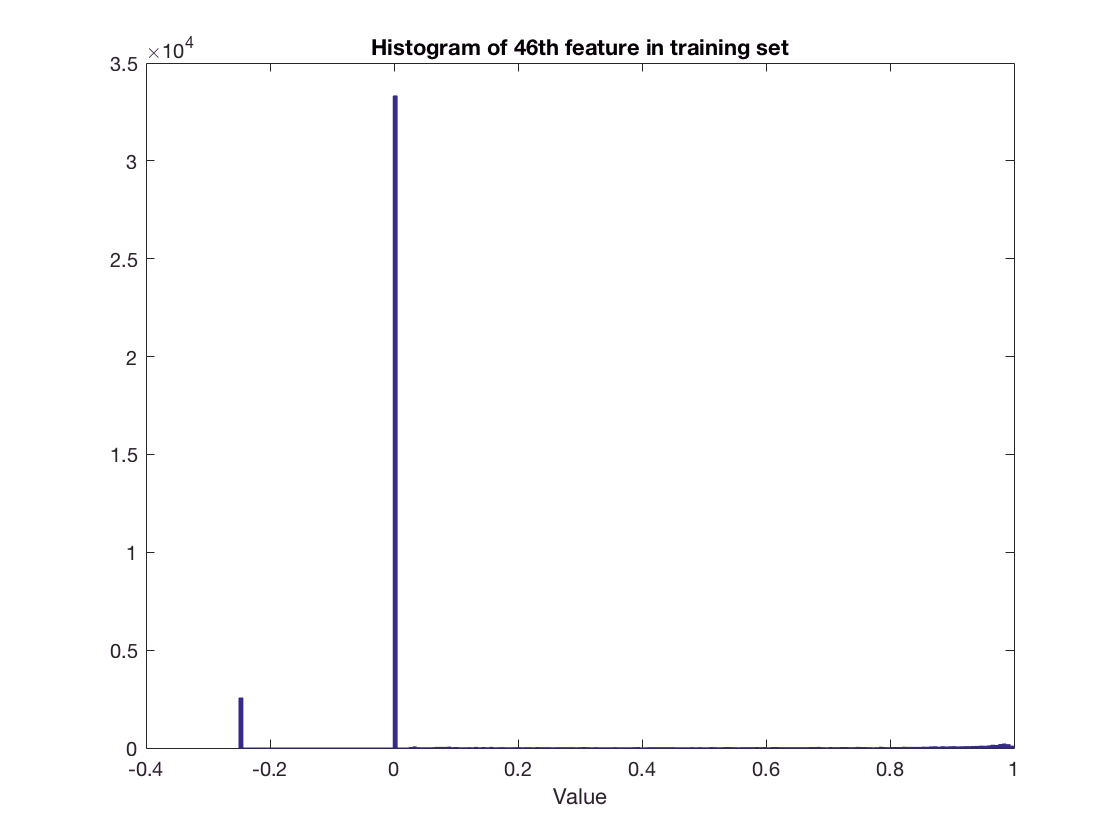

% Plot 46the feature in training set.
clf;  % necessary for working in Matlab's Live Script environment
hist(X_train(:, 46), sqrt(size(X_train, 1)));
title('Histogram of 46th feature in training set');
xlabel('Value');

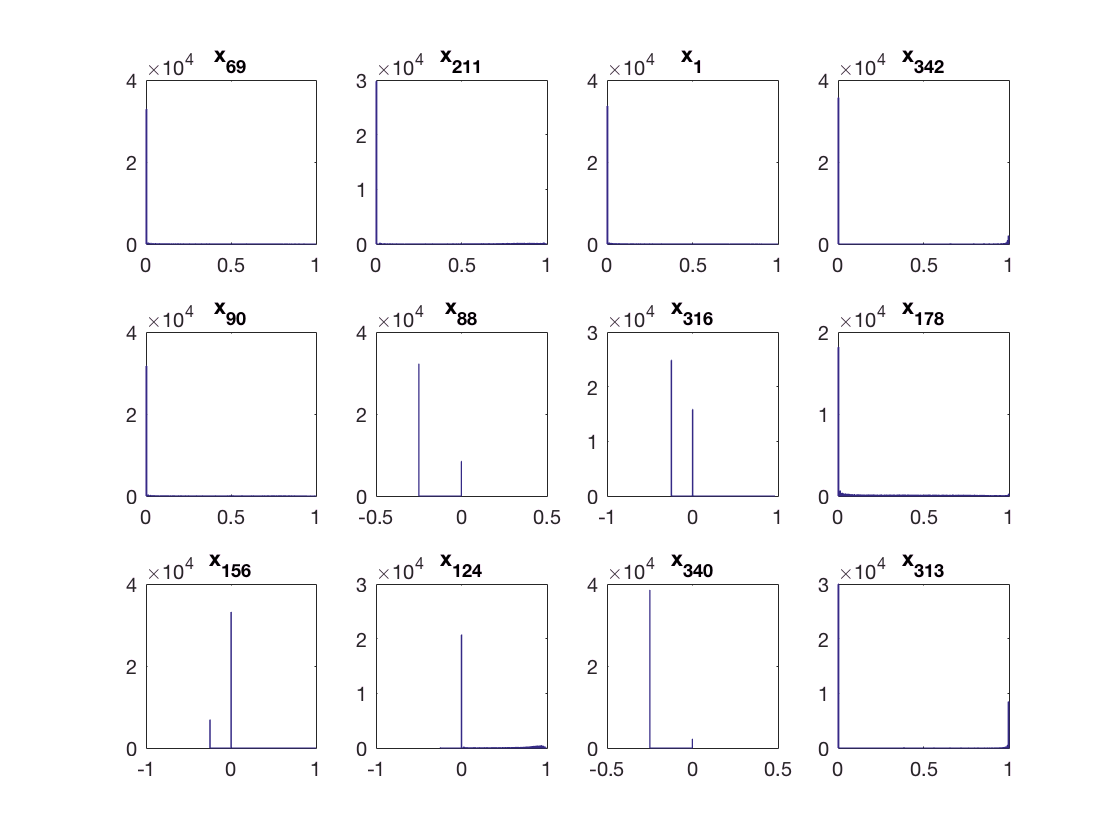


% Plot grid of other features (chosen randomly).
% Identify bounds of grid.
grid_size = [3 4];
num_plots = grid_size(1) * grid_size(2);

% Randomly select feature columns from training set.
rng(20161122);
cols = randperm(size(X_train, 2));
cols = cols(1:num_plots);

bins = sqrt(size(X_train, 1));  % for histogram
plot_num = 1;

% Plot histogram for each feature.
for col = cols
    
    subplot(grid_size(1), grid_size(2), plot_num);
    hist(X_train(:, col), bins);
    title('x_{' + string(col) + '}');
    plot_num = plot_num + 1;
    
end

It seems that many (if not all) features are highly concentrated at just one or two values.


% Get fraction of all values in training set that equal -0.25.
mean(mean(X_train == -0.25))

ans = 0.1487


% Get fraction of all values in training set that equal 0.
mean(mean(X_train == 0))

ans = 0.6580


% Add extra binary features.
aug_fn = @(X) [X X==0 X<0];
X_train_binary = aug_fn(X_train);

[ww, bb] = fit_linreg(X_train_binary, y_train, alpha);
ff = X_train_binary * ww + bb;


% Calculate training error.
rmse(ff - y_train)

ans = 0.3178


% Calculate validation error.
ff = aug_fn(X_val) * ww + bb;
rmse(ff - y_val)

ans = 0.3770

We expect the training error to go down for the same reason as before: we are adding extra features and perhaps representing the data in a way that better represents the relationship between the inputs and outputs within our model. At the very least, we will still capture the "noise" introduced from the augmented data, decreasing our training error and perhaps overfitting as well.

## Question 4: Invented classification tasks.

sigmoid = @(aa) 1./(1 + exp(-aa));

K = 10;
mx = max(y_train); mn = min(y_train); hh = (mx-mn)/(K+1);
thresholds = mn+hh:hh:mx-hh;

% Initialize values.
D = size(X_train, 2);
W = zeros(D, K);
B = zeros(K, 1);
sigma_train = zeros(size(X_train, 1), K);
sigma_val = zeros(size(X_val, 1), K);

for kk = 1:K
    
    % Get labels and fit.
    labels = y_train > thresholds(kk);
    [console_output, ww, bb] = evalc('fit_logreg_gradopt(X_train, labels, alpha);');
    
    % Save weights.
    W(:, kk) = ww;
    B(kk) = bb;
    
    % Predict on training and validation data.
    sigma_train(:, kk) = sigmoid(X_train * ww + bb);
    sigma_val(:, kk) = sigmoid(X_val * ww + bb);
    
end


[ww, bb] = fit_linreg(sigma_train, y_train, alpha);

% RMSE for training set.
ff = sigma_train * ww + bb;
rmse(ff - y_train)

ans = 0.1380


% RMSE for validation set
ff = sigma_val * ww + bb;
rmse(ff - y_val)

ans = 0.2515

This performance is much better than PCA because it effectively has a hidden layer, which allows it to capture higher-level "features" (to use neural net terminology, even if the weights are trained differently).

## Question 5. Small neural network.

% Train neural net using a sensible randomization of parameters.

% Dimension reminders:
% ww Kx1 hidden-output weights
% bb 1x1 output bias
% V KxD hidden-input weights
% bk Kx1 hidden biases

D = size(X_train, 2);

% "Sensible" weights. If I wanted to get fancier I could've used GlorotInit:
% http://www.inf.ed.ac.uk/teaching/courses/mlp/2016/mlp06-enc.pdf
ww_init = 0.1 * randn(K, 1) / sqrt(K);
bb_init = randn(1) / sqrt(K);
V_init = 0.1 * randn(K, D) / sqrt(D);
bk_init = randn(K, 1) / sqrt(D);

init = {ww_init, bb_init, V_init, bk_init};
[console_output, ww1, bb1, V1, bk1] = evalc('fit_nn_gradopt(X_train, y_train, alpha, init);');


% Calculate RMSE for training.
ff1 = nn_cost({ww1, bb1, V1, bk1}, X_train);
rmse(ff1 - y_train)

ans = 0.1135


% Calculate RMSE for validation.
ff1 = nn_cost({ww1, bb1, V1, bk1}, X_val);
rmse(ff1 - y_val)

ans = 0.2617


% Now initialize using weights from Q4.
init = {ww, bb, W', B};  % W' and B from Q4 are used as V and bk, respectively
[console_output, ww2, bb2, V2, bk2] = evalc('fit_nn_gradopt(X_train, y_train, alpha, init);');


% Calculate RMSE for training.
ff2 = nn_cost({ww2, bb2, V2, bk2}, X_train);
rmse(ff2 - y_train)

ans = 0.1147


% Calculate RMSE for validation.
ff2 = nn_cost({ww2, bb2, V2, bk2}, X_val);
rmse(ff2 - y_val)

ans = 0.2600

Initializing using the weights from Question 4 works slightly better than using sensible but random initial weights. However, the performance using neural nets does not work as well as the model from Question 4.

## Question 6. What next?

*Tweaking *$\alpha$

One obvious thing to try is tweaking $\alpha$. Andrew Ng, in his Coursera cour on machine learning ([https://www.coursera.org/learn/machine-learning](https://www.coursera.org/learn/machine-learning)), suggests scaling hyperparameters by factors of 3 when testing values. I therefore tried the values $\alpha ={\left\lbrace 3^z {\text{ }\alpha }_{\text{orig}} \right\rbrace }_{z\text{ }=\text{ }−4}^4$, with $\alpha_{orig} =10$ as the "original" alpha. (Perhaps that's not the best notation; see the definition of `alphas` below for what this means in the code.) I used the weights obtained from Question 4 to initialize the neural net weights since these worked best out of the neural net models.

testing alpha 0.12346...
testing alpha 0.37037...
testing alpha 1.1111...
testing alpha 3.3333...
testing alpha 10...
testing alpha 30...
testing alpha 90...
testing alpha 270...
testing alpha 810...
 
best alpha:                      3.3333
training error for best alpha:   0.13008
validation error for best alpha: 0.25224


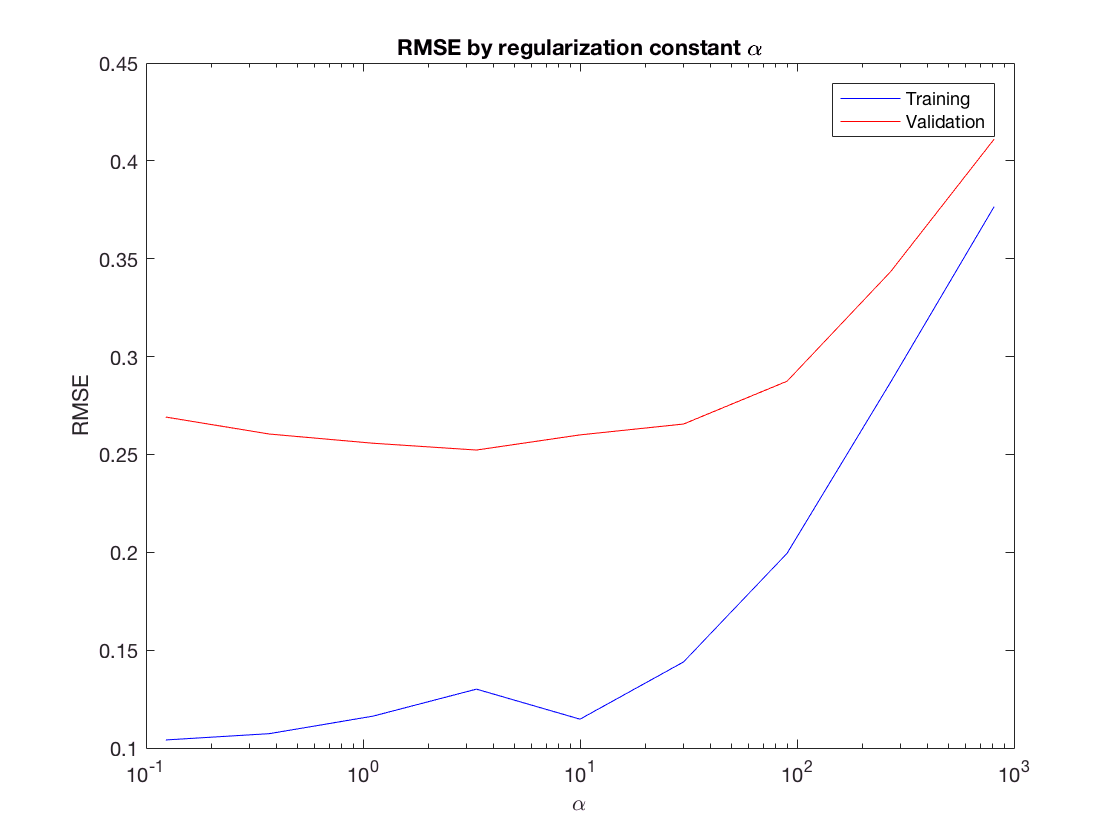

init = {ww, bb, W', B};
alpha_orig = 10;
alphas = alpha_orig * 3 .^ (-4:4);
data = {X_train, y_train, X_val, y_val};
[alpha_idx, E_train, E_val] = find_best_alpha_for_nn(init, data, alphas, 1);

A value of $\alpha \approx 3$ seems to give better validation error at 0.2522, beating the neural net models from Question 5.

*Using extra binary features*

I didn't include the code here, but I also tried augmenting the data using `aug_fn` from Question 3 Part b and using this as my training data for the neural net. This gave a validation error of 0.2725, which is a bit worse than the neural net models from Question 5.

## Appendix: created functions

Does not include functions given for assignment.

% Plot histogram of distribution and print mean with error bars.

function nada = explore_dist(yy, title_str)

    % Calculate standard error.
    stderr = std(yy) / sqrt(size(yy, 1));
    disp(strcat('mean = ' + string(mean(yy)) + ' +/- ' + stderr))
    
    % Plot histogram with mean and standard error.
    hist(yy, sqrt(size(yy, 1)));
    title(title_str);
    xlabel('CT scan slice location');
    
end

% Find best value of alpha for neural net model.
function [alpha_idx, E_train, E_val] = find_best_alpha_for_nn(init, data, alphas, make_plot)

    % Unpack data.
    X_train = data{1};
    y_train = data{2};
    X_val = data{3};
    y_val = data{4};
    
    % Initialize error vectors.
    E_val = zeros(size(alphas));
    E_train = zeros(size(alphas));
    alpha_idx = 1;
    
    for alpha = alphas
        
        disp('testing alpha ' + string(alpha) + '...');
        
        [console_output, ww, bb, V, bk] = evalc('fit_nn_gradopt(X_train, y_train, alpha, init);');

        % Calculate RMSE for training.
        ff = nn_cost({ww, bb, V, bk}, X_train);
        E_train(alpha_idx) = rmse(ff - y_train);

        % Calculate RMSE for validation.
        ff = nn_cost({ww, bb, V, bk}, X_val);
        E_val(alpha_idx) = rmse(ff - y_val);

        alpha_idx = alpha_idx + 1;

    end

    % Get alpha value with lowest validation error and report errors for
    % that alpha.
    [M, alpha_idx] = min(E_val);
    alpha_best = alphas(alpha_idx);
    disp(' ');
    disp('best alpha:                      ' + string(alpha_best));
    disp('training error for best alpha:   ' + string(E_train(alpha_idx)));
    disp('validation error for best alpha: ' + string(E_val(alpha_idx)));
    
    if make_plot
    
        % Create plot for training and validation errors by alpha.
        clf;
        semilogx(alphas, E_train, 'b');
        hold on;
        semilogx(alphas, E_val, 'r');
        title('RMSE by regularization constant \alpha');
        legend('Training', 'Validation');
        xlabel('\alpha');
        ylabel('RMSE');
        hold off;
    
    end

end

% Fit linear regression.
function [ww, bb] = fit_linreg(X, yy, alpha)
    
    % Add row of ones to data.
    N = size(X, 1);
    Phi = [ones(N, 1), X];

    % Create regularized data.
    K = size(Phi, 2);
    Phi_reg_addon = sqrt(alpha) * eye(K);
    Phi_reg_addon(1, 1) = 0;  % easy way to make sure we don't regularize the bias term
    Phi_reg = [Phi; Phi_reg_addon];
    y_reg = [yy; zeros(K, 1)];
    
    % Fit weights and get fitted y values. Predict using ff = Phi * w_fit.
    w_fit = Phi_reg \ y_reg;
    bb = w_fit(1);
    ww = w_fit(2:end);

end

% Fit logistic regression.
function [ww, bb] = fit_logreg_gradopt(X, yy, alpha)
    D = size(X, 2);
    num_line_searches = 500;
    init = {zeros(D,1), 0};
    param = minimize(init, @logreg_cost, -num_line_searches, X, yy, alpha);
    ww = param{1};
    bb = param{2};
end

% Fit neural net.
function [ww, bb, V, bk] = fit_nn_gradopt(X, yy, alpha, init)
    num_line_searches = 500;
    param = minimize(init, @nn_cost, -num_line_searches, X, yy, alpha);
    ww = param{1};
    bb = param{2};
    V = param{3};
    bk = param{4};
end

% Calculate root-mean-square error.
function E_rmse = rmse(E_vector)
    E_rmse = sqrt(mean((E_vector).^2));
end